# 2. Finding Natural Patterns in Data

## Dimensionality Reduction

When the dimension is large, it is difficult to visualize the data to look for patterns or groups. You can try to visualize the data by transforming it into a 2 or 3 dimenstional coordinate space.

load('bbstats.mat')

### 1. Multidimensional scaling

% open("2_1 Multidimensional Scaling.pdf") % Read this file before start
d= pdist(statsnorm);
[X,e]=cmdscale(d)

X =    -2.5485    1.2178   -0.0925   -0.7242   -0.4860   -0.0325    0.0950   -0.2356   -0.2837   -0.0311    0.2154   -0.3464    0.2172    0.0978   -0.0238   -0.0171   -0.0054
    2.1322   -3.1352    0.3102   -0.3670    0.3826    0.3179   -1.2126   -0.9061   -1.0428    0.1654    0.3707   -0.0027    0.2806   -0.0609   -0.0598    0.0183   -0.0009
   -0.5333    0.3654    0.7177   -0.3299   -0.3373    0.2117   -0.1612    0.2554   -0.3007    0.3865   -0.0195   -0.2278   -0.2815   -0.1042   -0.0117    0.0792    0.0072
    5.6463    2.3930    0.8472   -1.4487   -0.0339    0.2938   -0.2370    0.1329    0.2902   -0.3182   -0.1195   -0.1888   -0.2257    0.0342   -0.1956    0.0093    0.0063
   -2.6830    1.7338    0.0975    0.5254   -0.6947    0.3721   -0.4348    0.1247    0.3378   -0.8879    0.1100    0.3024    0.1182    0.0186   -0.0138   -0.0294   -0.0056
    5.5690   -4.4839    0.8503    0.2245    0.0946   -0.3723    0.5065    0.2828    0.8058    0.0967    0.2446    0.3213    0.3334   -0.4159 

e = 	1.0e+03 *

    9.4009
    5.1765
    1.2410
    0.7806
    0.4912
    0.4028
    0.3401
    0.2905
    0.2732
    0.1683


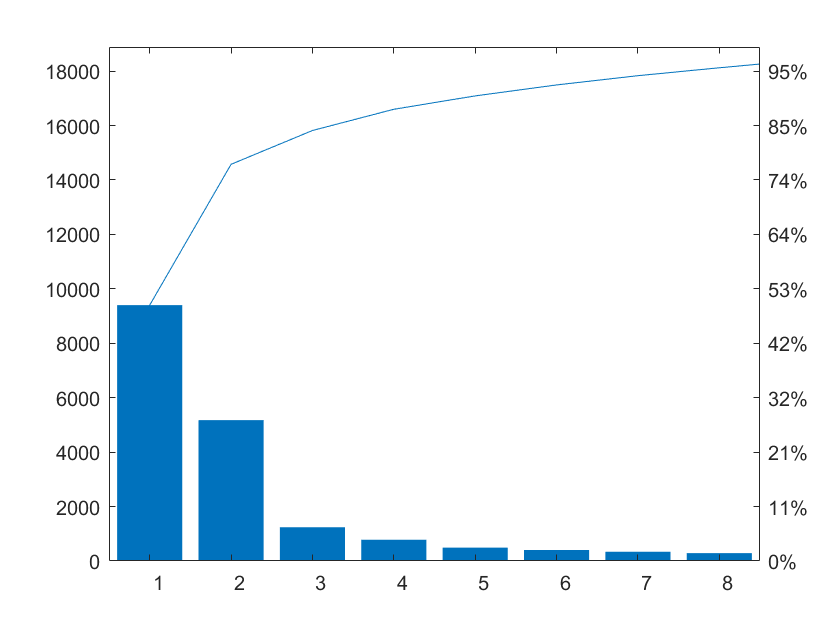

pareto(e)

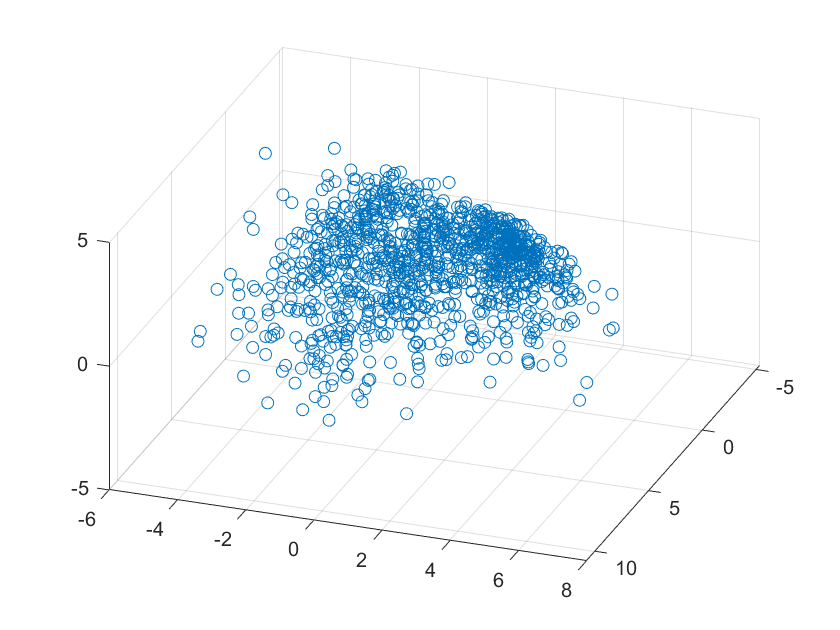

figure()
scatter3(X(:,1),X(:,2),X(:,3))
view(110,40)

### 2. Principal Component Analysis

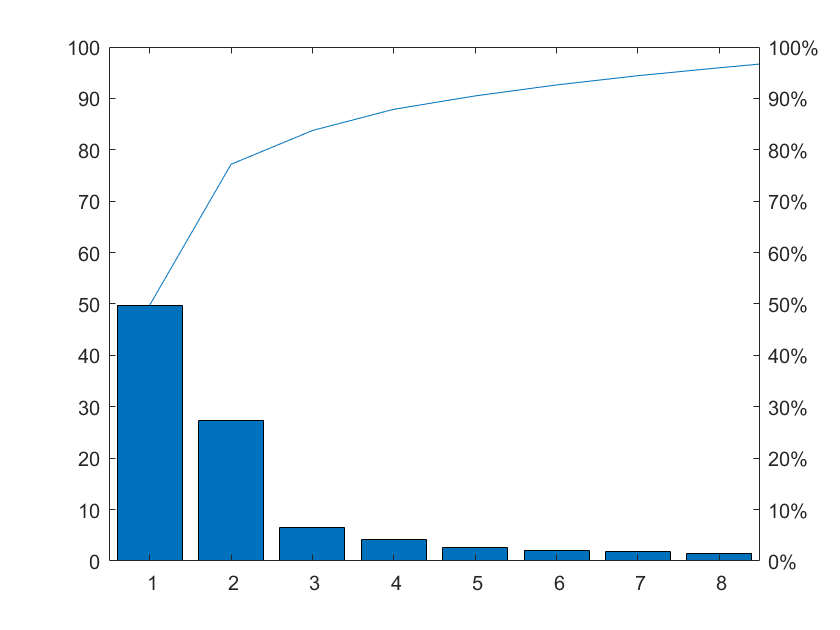

% open("2_2 Principal Component Analysis.pdf") % Read this file before start
[pcs,scrs,~,~,pexp]=pca(statsnorm);
pareto(pexp)

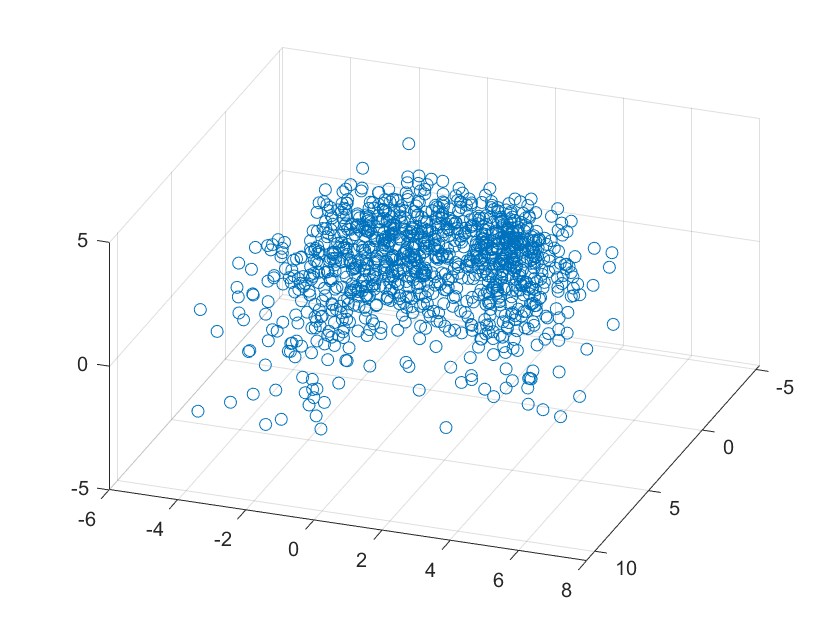

figure()
scatter3(scrs(:,1),scrs(:,2),scrs(:,3))
view(110,40)

## Unsupervised Learning

### 1. k-Means Clustering(1/3)

% open("2_3 k-Means Clustering.pdf") % Read this file before start
g = kmeans(statsnorm,2);
[g, c] = kmeans(statsnorm,2,'Replicates',5)

g =      2
     1
     2
     1
     2
     1
     2
     2
     1
     2


c =    -0.1170   -0.1298    1.1647    1.1771    0.4239    0.7808    0.8182    0.8762    0.2907    1.1174    0.6574    1.1608    1.1618    1.0581    1.0821    0.5798    0.5590
    0.0535    0.0594   -0.5327   -0.5384   -0.1939   -0.3571   -0.3742   -0.4008   -0.1330   -0.5111   -0.3007   -0.5310   -0.5314   -0.4840   -0.4950   -0.2652   -0.2557


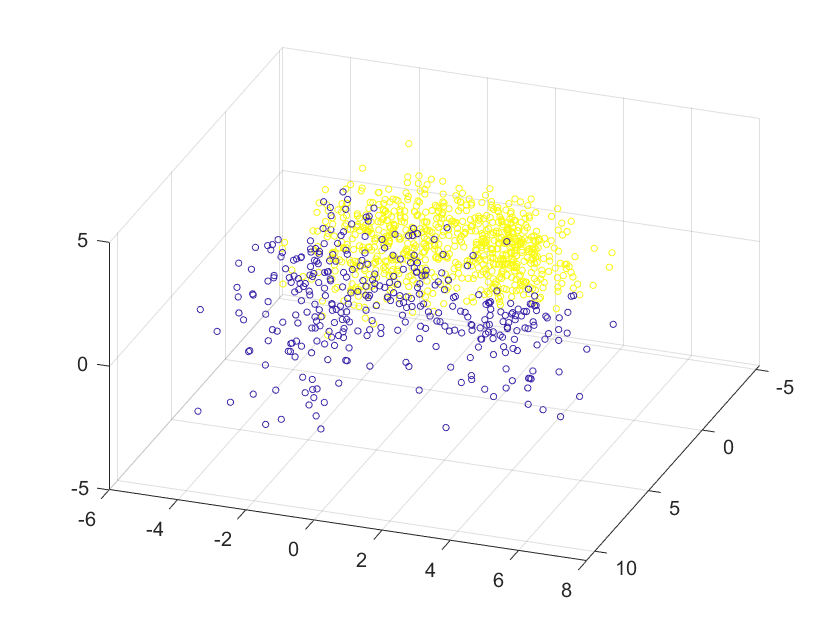

scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)
view(110,40)

### 2. Gaussian Mixture Model(2/3)

Grouping by GMM depends on parameter options. Try different 'RegularizationValue', 'CovarianceType' options.

% open("2_4 GMM Clustering.pdf") % Read this file before start
gm = fitgmdist(statsnorm,2,'Replicates',5,'RegularizationValue',0.02); % Fit GMM to 'statsnorm' Data

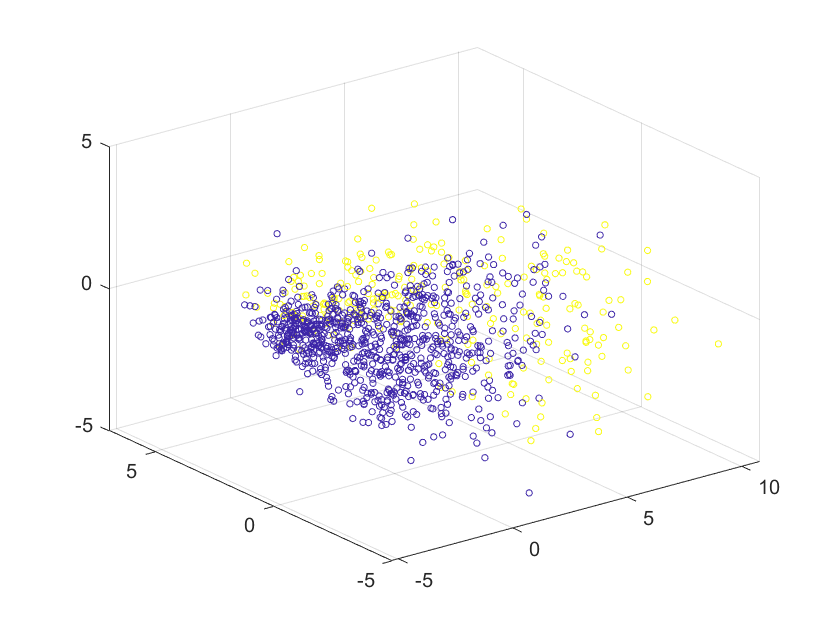


% Use 2 instead of 1, because probability results are always helpful
g = cluster(gm, statsnorm); % 1. Cluster statsnorm according to the GMM and Output the grouping results
[g,~,p] = cluster(gm, statsnorm); % 2. Cluster statsnorm according to the GMM and Output the grouping and probability results  

% Visualize groups
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,g)

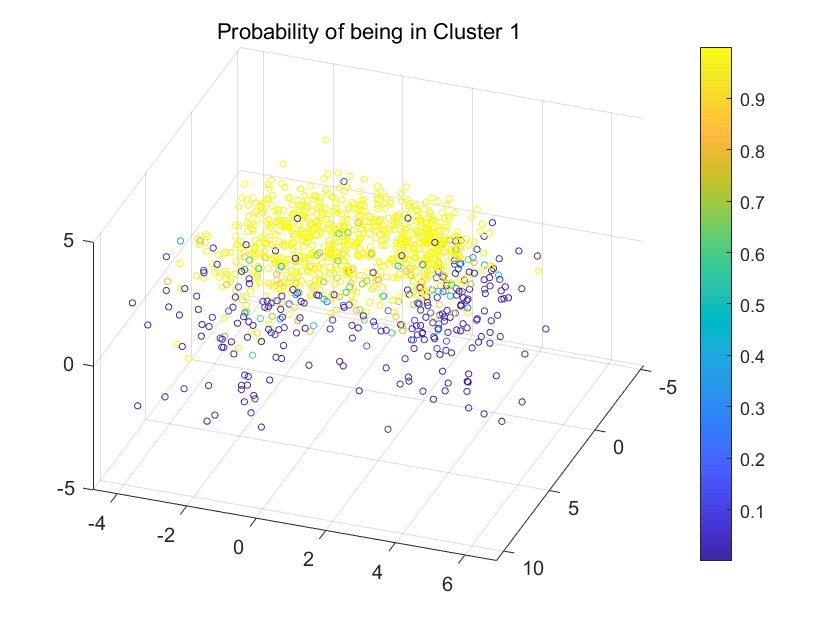


% Visualize probabilities
scatter3(scrs(:,1),scrs(:,2),scrs(:,3),10,p(:,1))
colorbar
view(110,40)
title('Probability of being in Cluster 1')

### 3. Interpreting the Groups

1. Visualizing observations in cluseters grouped by k-Means

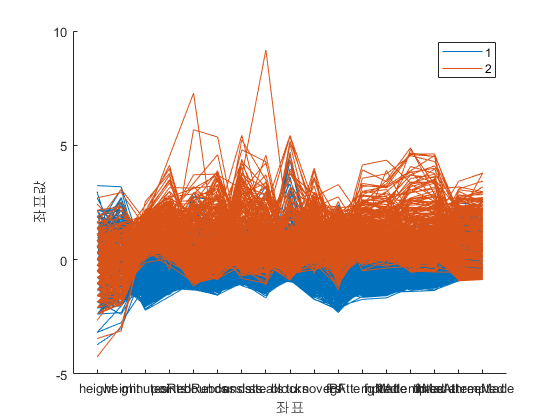

[g, c]= kmeans(statsnorm,2,"Replicates",5);

% 'parallelcoords' function to visualize observation in clussters
parallelcoords(statsnorm,"Group",g) % Is it discrete visualization?
xticklabels(labels)

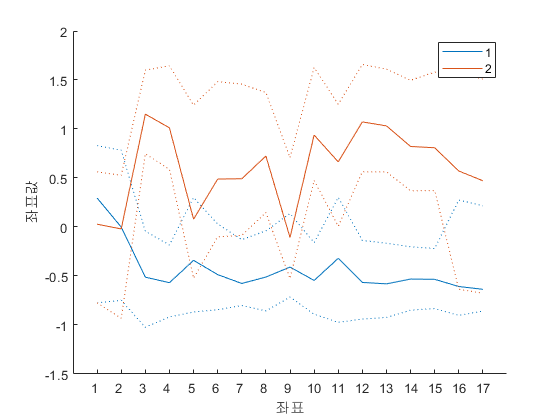

parallelcoords(statsnorm,"Group",g,"Quantile",0.25) % Much better now

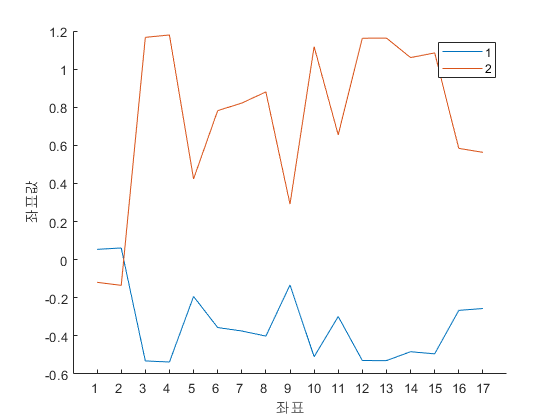

parallelcoords(c,"Group",1:2) % Use the centroid to visualize

2. Correlation between the groups and player positions (IMPORTANT because you can visualize clustering quality)

% counts = crosstab(yCat,grp)

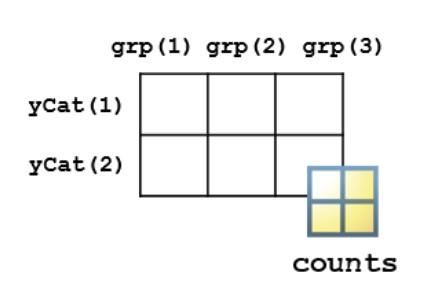

positions= categories(data.pos)

positions = 7×1 cell 배열
    {'G'  }
    {'G-F'}
    {'F-G'}
    {'F'  }
    {'F-C'}
    {'C-F'}
    {'C'  }


counts1=crosstab(data.pos,g)

counts1 =    239   128
    60    39
    28    21
   230    86
    75    43
    37     7
    95    24


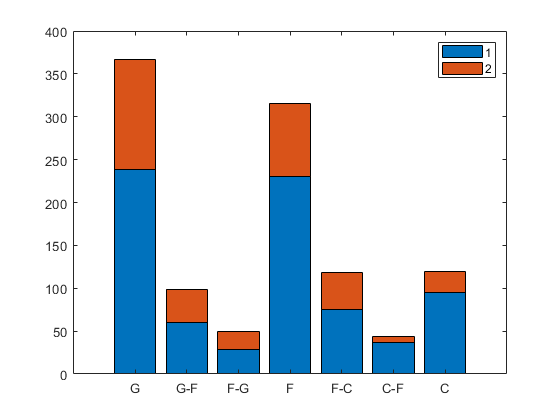

figure
bar(counts1,"stacked")
xticklabels(positions)
legend('1','2')

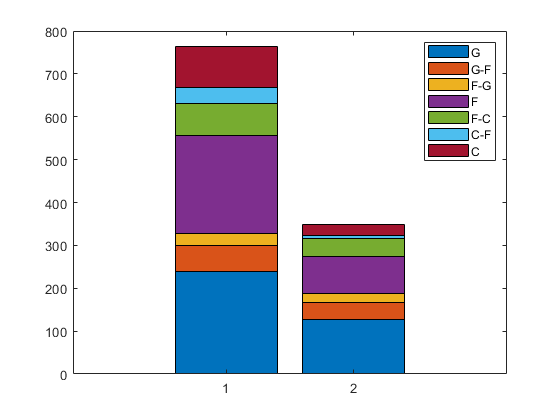



counts2=crosstab(g,data.pos);

figure
bar(counts2,"stacked");
xticklabels({'1','2'})
legend(positions)

### 4. Evaluating Clustering Quality

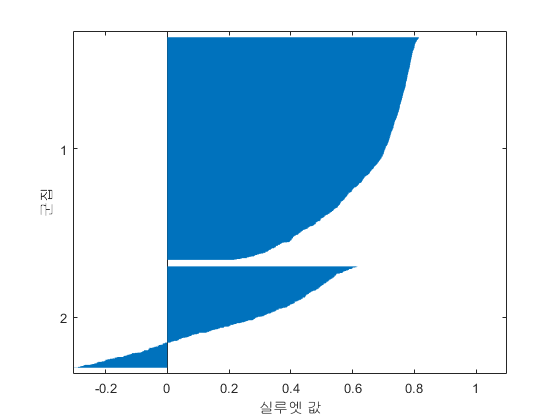

% Group data into 2~5 clusters and see their silhouette values.
% Is it easy to find the optimal number of clusters?
[g,c]=kmeans(statsnorm,2,"Replicates",5);
silhouette(statsnorm,g)

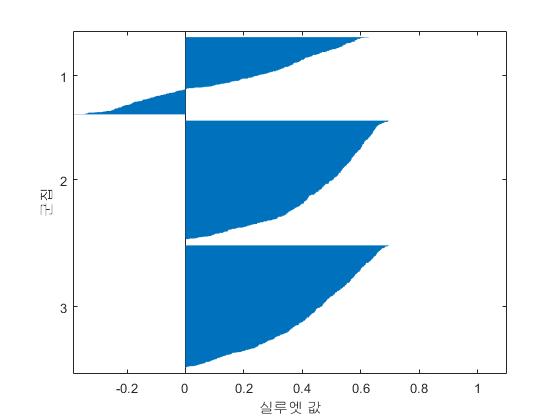

[g,c]=kmeans(statsnorm,3,"Replicates",5);
silhouette(statsnorm,g)

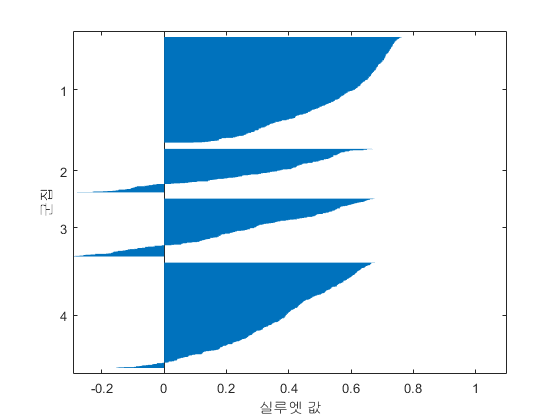

[g,c]=kmeans(statsnorm,4,"Replicates",5);
silhouette(statsnorm,g)

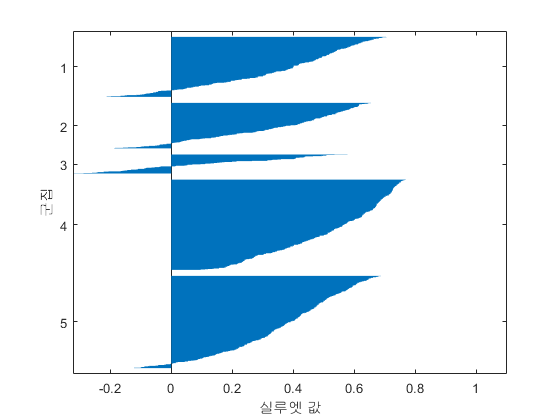

[g,c]=kmeans(statsnorm,5,"Replicates",5);
silhouette(statsnorm,g)



% 'evalclusters' function finds you the optimal number of clusters
clustEv1=evalclusters(statsnorm,"kmeans","silhouette","KList",2:5)

clustEv1 =   SilhouetteEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [0.5184 0.3821 0.3976 0.3631]
           OptimalK: 2


clustEv2=evalclusters(statsnorm,"kmeans","CalinskiHarabasz","KList",2:5)

clustEv2 =   CalinskiHarabaszEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [556.5509 471.1204 455.8580 417.8669]
           OptimalK: 2


clustEv3=evalclusters(statsnorm,"kmeans","DaviesBouldin","KList",2:5)

clustEv3 =   DaviesBouldinEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.3083 1.3180 1.2833 1.2688]
           OptimalK: 5


clustEv4=evalclusters(statsnorm,"kmeans","gap","KList",2:5)

clustEv4 =   GapEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.4523 1.5537 1.6547 1.7247]
           OptimalK: 5


### 5. Hierarchical Clustering(3/3)

% Extract the statistics only for player listed as guards
idx=data.pos=='G'

idx = 1112×1 logical 배열
   0
   1
   0
   0
   0
   1
   0
   1
   0
   0


numberOfGuard=sum(idx) %nnz(idx)

numberOfGuard = 367



% guardstats = statsnorm(idx,:)
guardstats=zscore(stats(idx,:)); % Try to use 'zscore' function this time

% Make a dendrogram of the guards' statistics
z=linkage(guardstats,'ward')

z =     6.0000  119.0000    0.7446
   20.0000  290.0000    0.8289
   15.0000   41.0000    0.8398
  106.0000  270.0000    0.8654
  181.0000  248.0000    0.8691
   35.0000  162.0000    0.9201
   27.0000   90.0000    0.9788
  228.0000  285.0000    0.9829
  203.0000  342.0000    0.9930
   22.0000  234.0000    0.9930


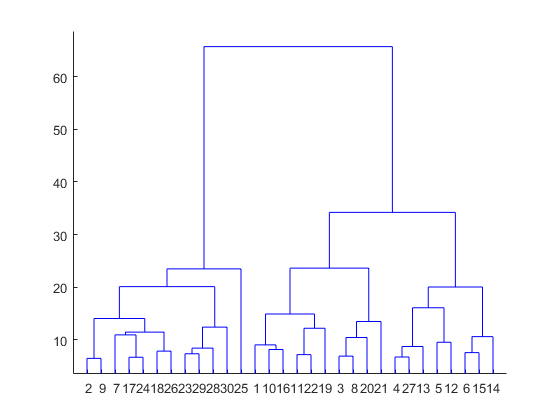

dendrogram(z)

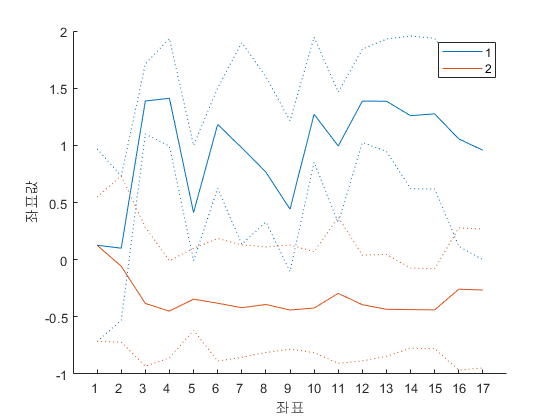



% Make and interpret clusters from the dendrogram
gc2=cluster(z,'maxclust',2);
gc3=cluster(z,'maxclust',3);

figure
parallelcoords(guardstats,'Group',gc2,'Quantile',0.25)

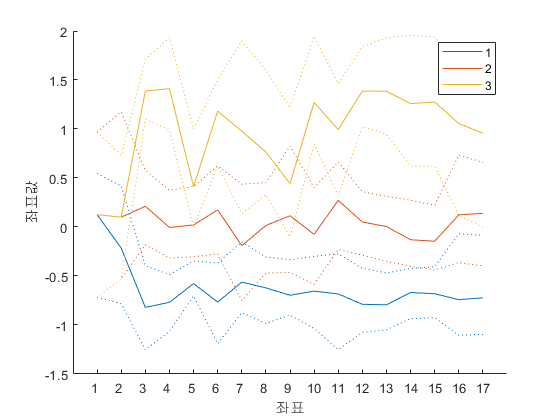

parallelcoords(guardstats,'Group',gc3,'Quantile',0.25)


% 'evalclusters' function with 'linkage' option
% also find you the optimal number of clusters
clustEv1=evalclusters(statsnorm,"linkage","silhouette","KList",2:5)

clustEv1 =   SilhouetteEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [0.5706 0.3457 0.3091 0.2577]
           OptimalK: 2


clustEv2=evalclusters(statsnorm,"linkage","CalinskiHarabasz","KList",2:5)

clustEv2 =   CalinskiHarabaszEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [411.0151 387.7741 383.7197 344.1431]
           OptimalK: 2


clustEv3=evalclusters(statsnorm,"linkage","DaviesBouldin","KList",2:5)

clustEv3 =   DaviesBouldinEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.1753 1.4775 1.2278 1.4924]
           OptimalK: 2


clustEv4=evalclusters(statsnorm,"linkage","gap","KList",2:5)

clustEv4 =   GapEvaluation - 속성 있음:

    NumObservations: 1112
         InspectedK: [2 3 4 5]
    CriterionValues: [1.4044 1.5300 1.6388 1.6845]
           OptimalK: 5
